% script for memory task anaysis

## Parameter Setting

subject ='Group';
plot_window=[1 25 1920 1080];
home_dir = '/bigvault/Projects/seeg_pointing';
group_dir = '/bigvault/Projects/seeg_pointing/results/memory_group/';

% obj_pic = 51:165; % original [-2,3], save [-0.5,1.5], pic [0,1.15]
% seq_pic = 251:500;% original [-5,7], save [-2.5,5], pic [0,2.5]
% seq_pre = 1:200;  % original [-5,7], save [-2.5,5], pre interval [-2.5,-0.5]
% seq_after = 501:700;% original [-5,7], save [-2.5,5], pre interval [2.5,4.5]

index = [7,13,25,31,43,49];
bd_id = [index,index+18*6]; 
non_bd_id = [index+18*3,index+18*9]; 

# RSA

- same VS different  picture RSA

- pre vs after RSA

## Neural Time Windows in Object Recognition Task 

% load
load([group_dir,'rsa_obj_group.mat'], 'rsa_group')
disp(['subject: ',num2str(rsa_group.sub_id)])

subject: 1   2   3   4   7  12  15  16  17  18  19  20  21  24  25  26


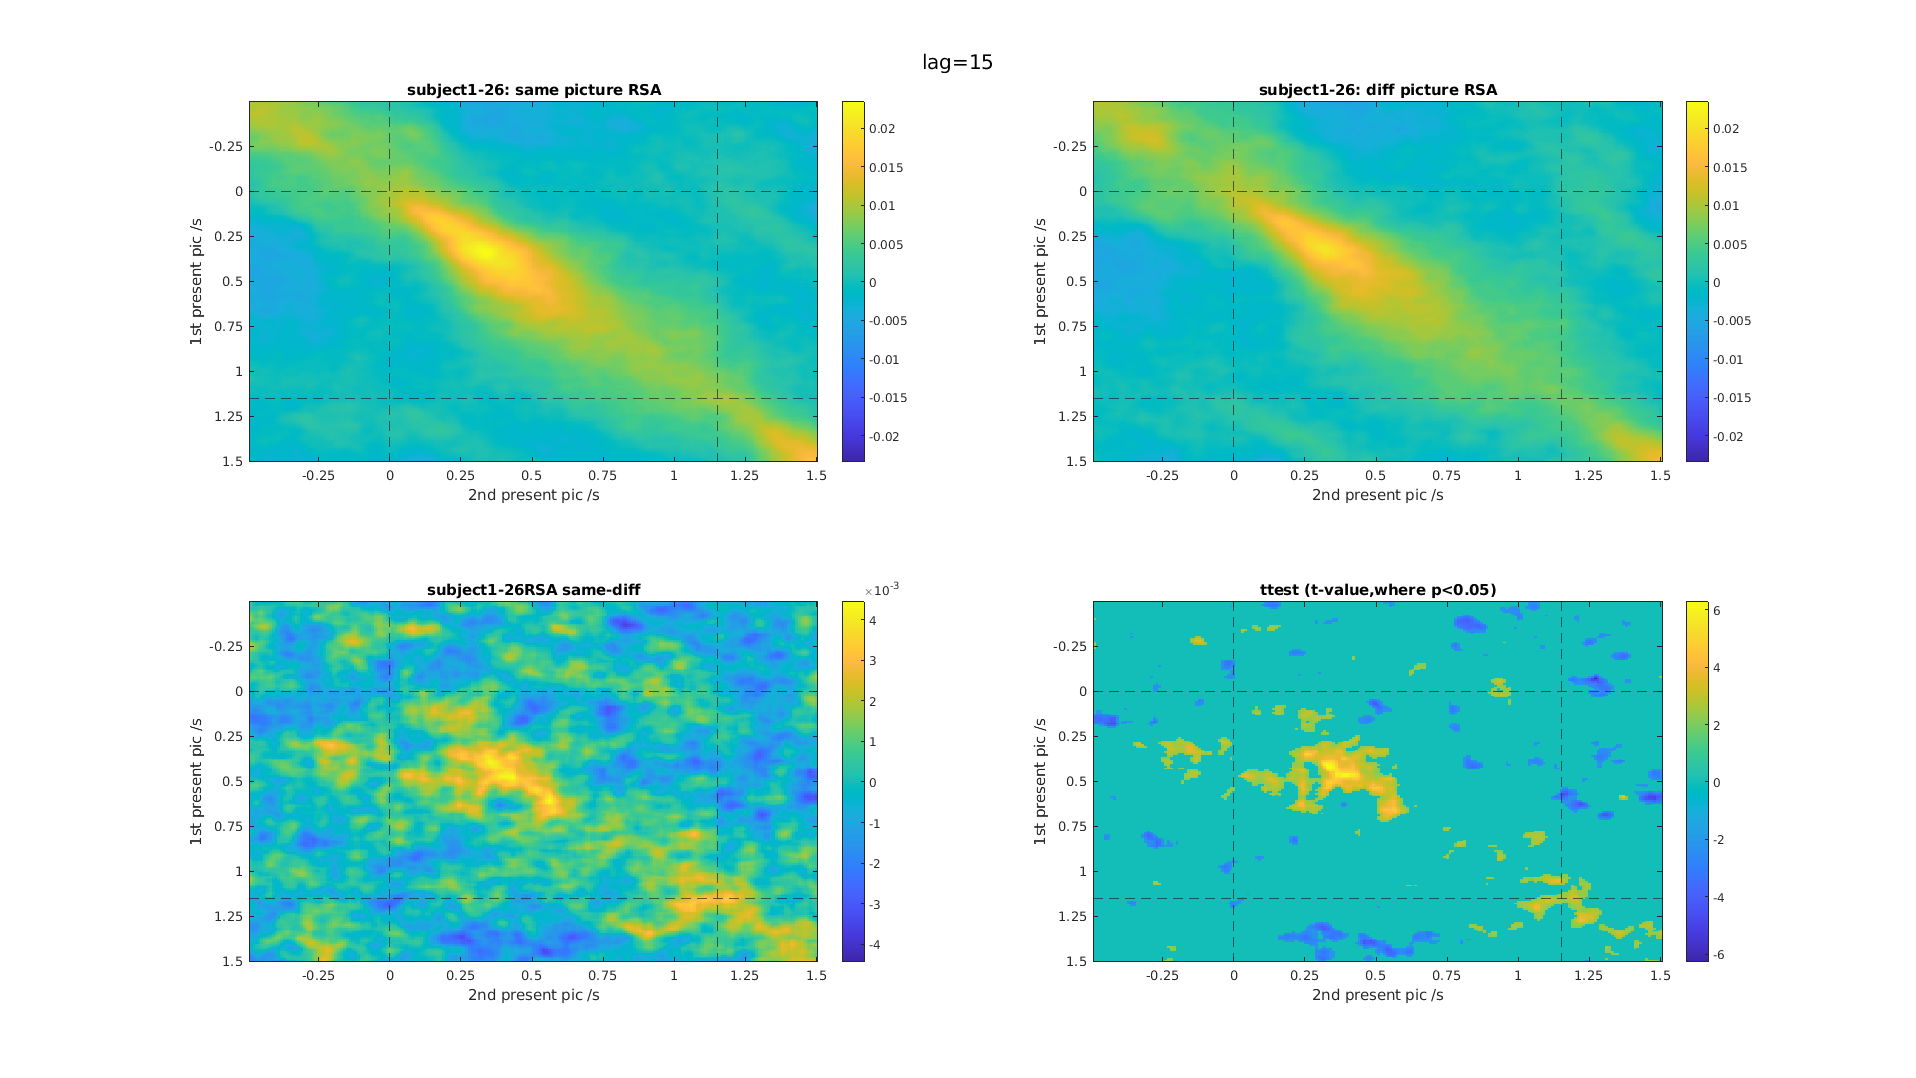

subject ='subject1-26';
rsa_same= rsa_group.same;
perm_result = [];
for lag = 15
    rsa_diff = rsa_group.diff{lag};
    figure
    plt_rsa_sd(rsa_same, rsa_diff,'obj');
    subplot(2,2,1);title([subject,': same picture RSA'])
    subplot(2,2,2);title([subject,': diff picture RSA'])
    subplot(2,2,3);title([subject,'RSA same-diff'])
    sgtitle(['lag=',num2str(lag)])
end

## Consistency of neural activity across Object and Sequence

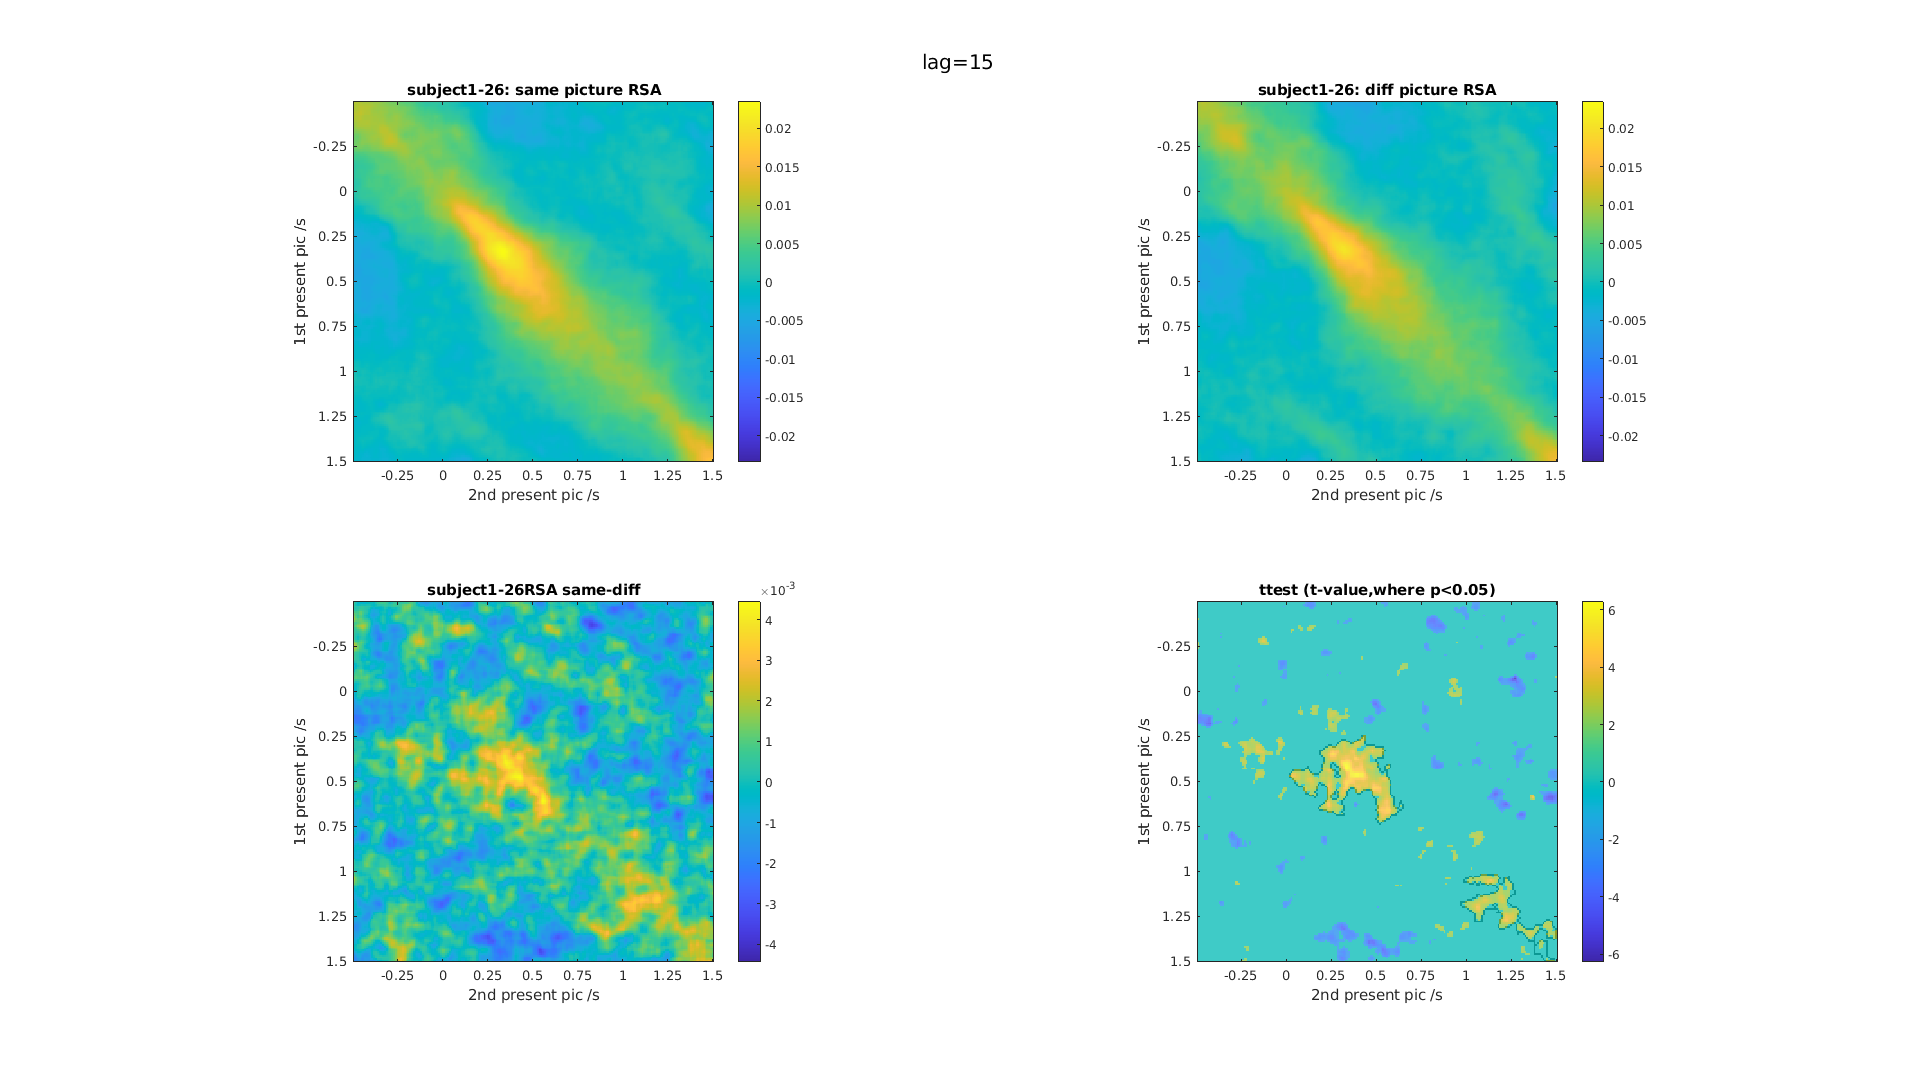

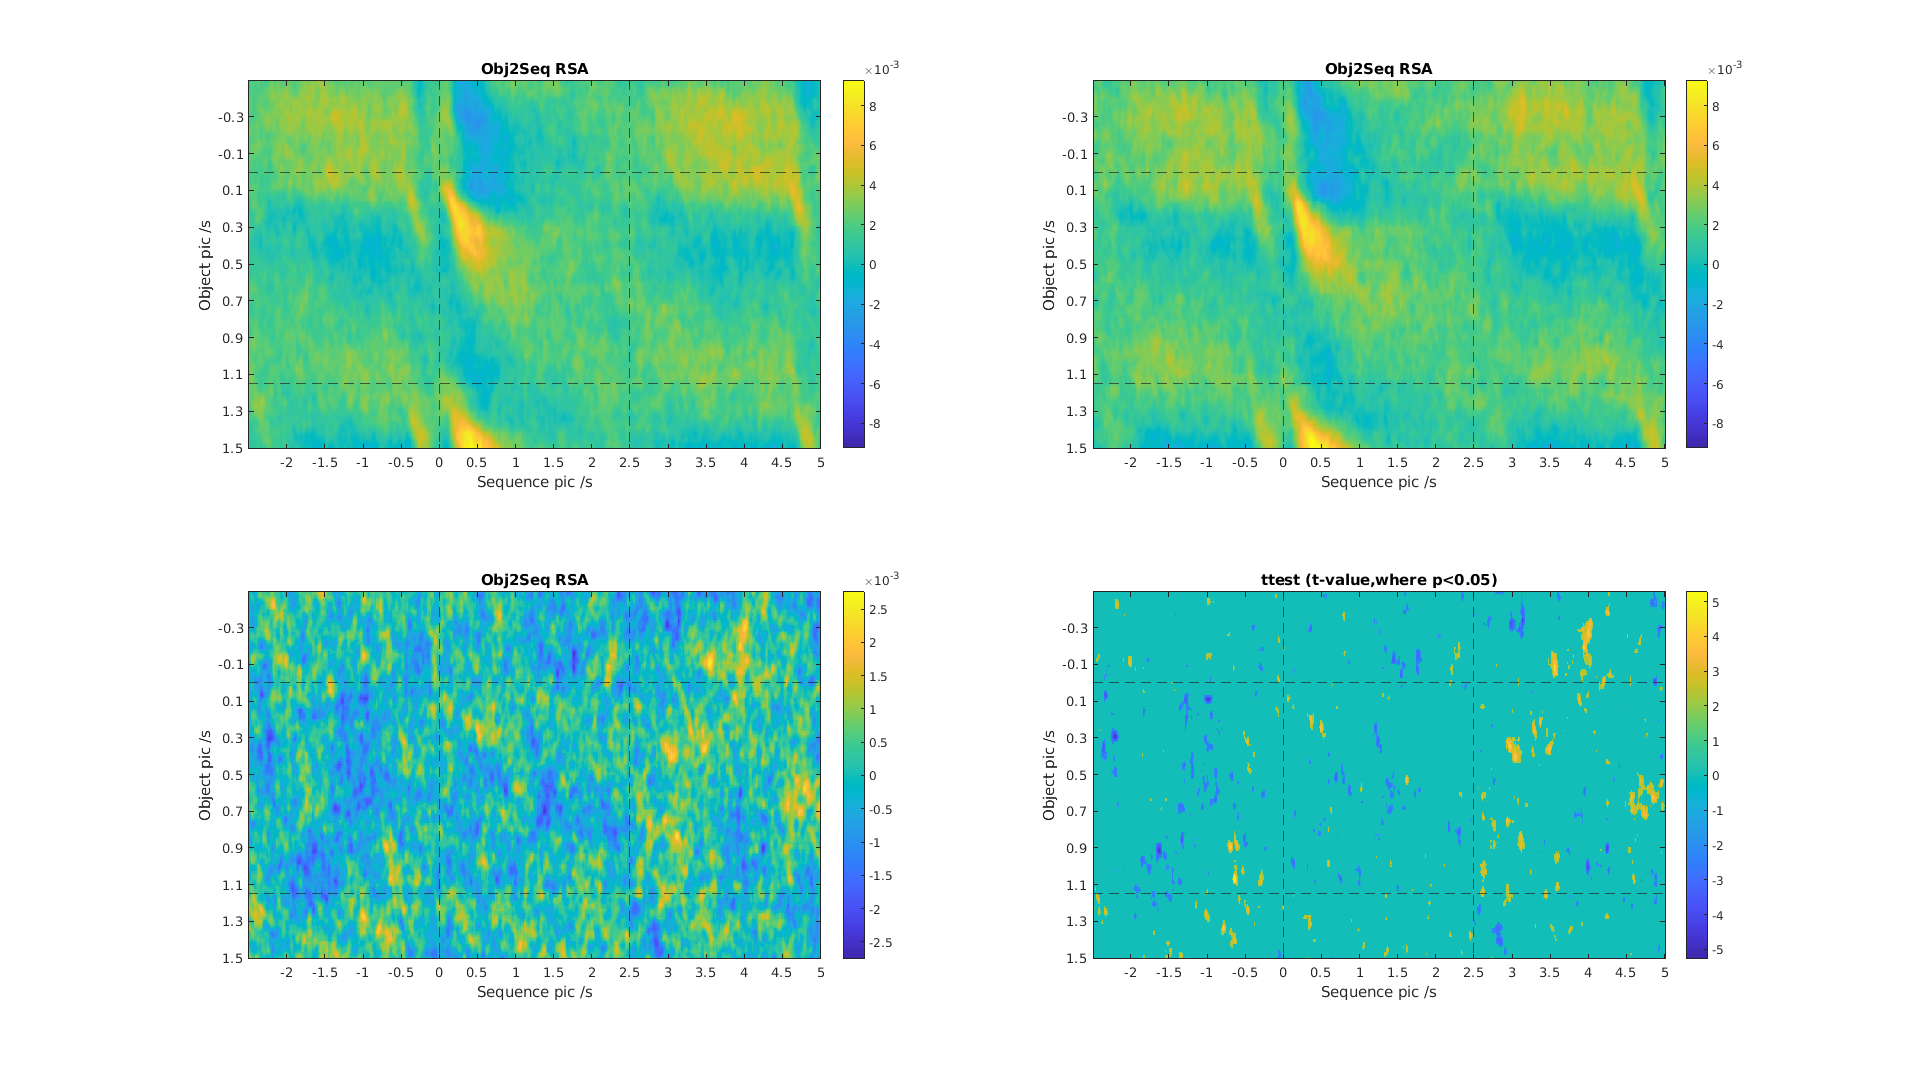

rsa_obj2seq_group = load_mat([group_dir,'rsa_obj2seq_group.mat']);
rsa_same = rsa_obj2seq_group.same;
rsa_diff = rsa_obj2seq_group.diff;
method = 'ttest';

% 4. obj2seq same difff
plt_rsa_sd(rsa_same,rsa_diff,'obj2seq');

% permutation time[501:750]
obj2seq_same = rsa_same(51:165,501:750,:);
obj2seq_diff = rsa_diff(51:165,501:750,:);
[clusters_perm, p_perm,~,~] = permutest(obj2seq_same,obj2seq_diff);

Unrecognized function or variable 'obj2seq_dsame'.


figure
i=1;
mask = zeros(size(obj2seq_same(:,:,1)));
mask(significant_clusters{1, i}) = 1;
title(['p=',num2str(p_perm(i))])


% 5. obj2seq flatten (to obj axis)
%plt_rsa_obj2seq_flatten(rsa_same, rsa_diff, 1, subject, plot_window)
plt_rsa_obj2seq_flatten(rsa_same, rsa_diff, 2, subject, plot_window)
% sequence 0-5s
plt_rsa_obj2seq_flatten(rsa_same(:,251:750,:), rsa_diff(:,251:750,:), 2, subject, plot_window)
sgtitle([subject,' reserve Sequence 0-5s'])
% sequence 0-4.5s
plt_rsa_obj2seq_flatten(rsa_same(:,251:700,:), rsa_diff(:,251:700,:), 2, subject, plot_window)
sgtitle([subject,' reserve Sequence 0-4.5s'])
% sequence 0-2.5s
plt_rsa_obj2seq_flatten(rsa_same(:,251:500,:), rsa_diff(:,251:500,:), 2, subject, plot_window)
sgtitle([subject,' reserve Sequence 0-2.5s'])

% sequence 2.5-4.5s
plt_rsa_obj2seq_flatten(rsa_same(:,501:750,:), rsa_diff(:,501:750,:), 2, subject, plot_window)
sgtitle([subject,' reserve Sequence 2.5-5s'])

% sequence 2.5-4.5s/5s
%plt_rsa_obj2seq_flatten(rsa_same(:,251:750,:), rsa_diff(:,251:750,:), 2, subject, plot_window)
%sgtitle([subject,' reserve Sequence 0-5s'])

% 5. obj2seq flatten (to seq axis)
% Object 0-1.15s
plt_rsa_obj2seq_flatten(rsa_same(51:165,:,:), rsa_diff(51:165,:,:), 1, subject, plot_window)
sgtitle([subject,' reserve Object 0-1.15s'])

% Object 0.25-0.75s
plt_rsa_obj2seq_flatten(rsa_same(76:125,:,:), rsa_diff(76:125,:,:), 1, subject, plot_window)
sgtitle([subject,' reserve Object 0.25-0.75s'])

% Object 1-1.25s
plt_rsa_obj2seq_flatten(rsa_same(151:175,:,:), rsa_diff(151:175,:,:), 1, subject, plot_window)
sgtitle([subject,' reserve Object 1-1.25s'])

## Consistency of neural activity across pre and after in Obj2Seq 

% 6. obj2seq region123 (same picture: pre vs after)
% contains fixation
plt_rsa_obj2seq_pre_after(rsa_same,subject,plot_window,method,'contains_fixation')
sgtitle([subject,': same picture(contains fixation)'])

% without fixation
plt_rsa_obj2seq_pre_after(rsa_same,subject,plot_window,method,'without_fixation')
sgtitle([subject,': same picture(without fixation)'])

# Boundary effect RSA?

## obj2sequence: boundary vs boundary

load(([group_dir,'rsa_obj2seq_bd.mat']))
obj2seq_bd = cell2matrix(rsa_group.bd);
obj2seq_non_bd = cell2matrix(rsa_group.non_bd);
plt_rsa_obj2seq_sd(obj2seq_bd,obj2seq_non_bd,'Group',plot_window)
subplot(2,2,1);title([subject,': Boundary RSA'])
subplot(2,2,2);title([subject,': non Boundary RSA'])
subplot(2,2,3);title([subject,': Boundary - non Boundary RSA'])

% calculate pic_coor_h
pic_corr_h=[];
for i=1:size(obj2seq_bd,1)
    for j=1:size(obj2seq_bd,2)
        [pic_corr_h(i,j),~]=ttest(squeeze(obj2seq_bd(i,j,:)),squeeze(obj2seq_non_bd(i,j,:)));
    end
end

% set mask
mask_temp{1,1} = [80:110];mask_temp{1,2} = [350:400];
mask_temp{2,1} = [125:160];mask_temp{2,2} = [365:405];
mask_temp{3,1} = [60:100];mask_temp{3,2} = [595:650];
mask_temp{4,1} = [175:200];mask_temp{4,2} = [660:750];

% plot mask
mask = zeros(200,750);
for i = 1:4
    mask(mask_temp{i,1},mask_temp{i,2})=1;
end
BW2 = bwperim(mask, 4);
figure;imagesc(mask.*pic_corr_h|BW2)

% plot mean value in each mask 

obj2seq1 = cell2matrix(rsa_group.bd);
obj2seq2 = cell2matrix(rsa_group.non_bd);
obj2seq = cat(3, cell2matrix(rsa_group.bd),cell2matrix(rsa_group.bd_pre),cell2matrix(rsa_group.non_bd),cell2matrix(rsa_group.non_bd_pre));
condition  = reshape(repmat([1,1,2,2], 20, 1),[],1);
position  = reshape(repmat([1,2,1,2], 20, 1),[],1);
figure
for i=1:4
    subplot(2,2,i)
    mask_bd = squeeze(mean(mean(obj2seq1(mask_temp{i,1},mask_temp{i,2},:),1),2));
    mask_non_bd = squeeze(mean(mean(obj2seq2(mask_temp{i,1},mask_temp{i,2},:),1),2));
    plt_bar_line([mask_bd ,mask_non_bd],{'pre boundary','boundary'})
    title(['Mask',num2str(i)])
end

% anova 
p=[];
for i = 1:size(obj2seq,1)
    for j=1:size(obj2seq,2)
        p(i,j,:) = anovan(squeeze(obj2seq(i,j,:)),{condition position},'model','interaction','varnames',{'condition','position'},'display','off');
    end
end

a = p; a(a<0.05)=-1; a(a>=0.05)=0; a=abs(a);
anovan_name = {'condition','position','condition*position'};
figure
for i= 1:4
    subplot(2,2,i)
    if i<4
        imagesc(a(:,:,i)|BW2)
        title(['anovan: ',anovan_name{i}])
    else
        imagesc(pic_corr_h|BW2)
        title('Mask')
    end
    yticks(0:20:200);
    yticklabels([-50:20:150]/100);
    ylabel('Object pic /s')
    yline(50,'--')
    yline(165,'--')
    xticks(0:50:750);
    xticklabels([-250:50:500]/100);
    xlabel('Sequence pic /s')
    xline(250,'--')
    xline(500,'--')
    colorbar()
end
set(gcf, 'Position', [1 25 1920 1080]);

## sequence2sequence: boundary vs boundary

% Atantion!!! the mean corr in this part is negtive
load(([group_dir,'rsa_seq_group.mat']))

### pic vs total

% plot seq_pic_total
plt_rsa_seq_pic_total(rsa_group.pic_total, subject, plot_window)

% current vs after
pic_total_bd = squeeze(mean(rsa_group.position.pic_total.bd,3));
pic_total_non_bd = squeeze(mean(rsa_group.position.pic_total.non_bd,3));
plt_rsa_seq_sd(pic_total_bd(:,501:700,:), pic_total_non_bd(:,501:700,:), subject, plot_window)

% boundary vs non bounday
pic_total_bd18 = rsa_group.position.pic_total.bd;
pic_total_non_bd18 = rsa_group.position.pic_total.non_bd;
ttest_h = [];
for pici =1:18
    for i =1:size(pic_total_bd,1)
        for j=1:size(pic_total_bd,2)
            ttest_h(i,j,pici)=ttest(pic_total_bd18(i,j,pici,:),pic_total_non_bd18(i,j,pici,:));
        end
    end
end
plt_pic18(ttest_h,'pic_total')

% boundary-6-before vs non_boundary-6-before (after-after)
plt_rsa_seq_sd(rsa_group.isnr.boundary, rsa_group.isnr.non_boundary, subject, plot_window)

% position
position_name ={'pic_total_bd','pic_total_pre_bd','pic_total_non_bd','pic_total_pre_non_bd'};
data_position.pic_total_bd = squeeze(mean(rsa_group.position.pic_total.bd(:,:,[7,13],:),3));
data_position.pic_total_pre_bd = squeeze(mean(rsa_group.position.pic_total.bd(:,:,[6,12],:),3));
data_position.pic_total_non_bd = squeeze(mean(rsa_group.position.pic_total.non_bd(:,:,[7,13],:),3));
data_position.pic_total_pre_non_bd = squeeze(mean(rsa_group.position.pic_total.non_bd(:,:,[6,12],:),3));

seq = [];
figure
for i = 1:4
    subplot(2,2,i)
    imagesc(mean(data_position.(position_name{i})(:,551:700,:),3))
    seq = cat(3,seq,data_position.(position_name{i}));
    colorbar()
end

condition  = reshape(repmat([1,1,2,2], 20, 1),[],1);
position  = reshape(repmat([1,2,1,2], 20, 1),[],1);
p=[];
for i = 1:size(seq,1)
    for j=1:size(seq,2)
        p(i,j,:) = anovan(squeeze(seq(i,j,:)),{condition position},'model','interaction','varnames',{'condition','position'},'display','off');
    end
end

% anova: condition * position
a = p; a(a<0.05)=-1; a(a>=0.05)=0; a=abs(a);
anovan_name = {'condition','position','condition*position'};
figure
for i= 1:3
    subplot(2,2,i)
    if i<4
        imagesc(a(:,:,i))
        title(['anovan: ',anovan_name{i}])
    else
        imagesc(pic_corr_h)
        title('Mask')
    end
    yticks(0:20:250);
    yticklabels([0:20:250]/100);
    ylabel('Object pic /s')
    xticks(0:50:750);
    xticklabels([-250:50:500]/100);
    xlabel('Sequence pic /s')
    xline(250,'--')
    xline(500,'--')
    colorbar()
end
set(gcf, 'Position', [1 25 1920 1080]);


### pre vs after

% 1-18 picture (pre vs after)
plt_pic18(mean(rsa_group.position.pre_after.bd,4),'pre_after')
sgtitle('Boundary: pre_after')

seq_pre = rsa_group.pic_total(:,1:200,:);
seq_after = rsa_group.pic_total(:,501:700,:);


# Item Specific Representation

## Pre/After  vs  current stimulus

% sequence2sequence
load([group_dir,'rsa_seq_pic_total_group.mat']);
rsa_seq = tanh(rsa_seq_pic_total_group.same);
%rsa_seq(rsa_seq==inf)= nan;

% pic vs total 
plt_rsa_seq_pic_total(tanh(rsa_seq), subject, plot_window)

# Hippocampus

## Neural Time Windows in Object Recognition Task 

## Consistency of neural activity across Object and Sequence

## Consistency of neural activity across pre and after in Sequence 

## Pre/After  vs  current stimulus

## Power change in Boundary and Nonboundary

%wavelet_subject = load_mat('/bigvault/Projects/seeg_pointing/results/sequence_memory/Hippocampus_subject.mat');

[wavelet_boundary,idx] = cell2matrix(wavelet_subject.data_bd);
[wavelet_non_boundary,idx] = cell2matrix(wavelet_subject.data_non_bd);

## channel 2 subject

wavelet_subject = [];

subjects =unique(wavelet_group.info(:,1))
for j = 1:length(subjects)
    subject=subjects(j);
    ids = find(wavelet_group.info(:,1)==subject);
    for i=1:18
        wavelet_subject.data_bd{subject,i} = mean(cell2matrix(wavelet_group.data_bd(ids,i)),3);
        wavelet_subject.data_non_bd{subject,i} = mean(cell2matrix(wavelet_group.data_non_bd(ids,i)),3);
    end
end
wavelet_subject.info = wavelet_group.info;
wavelet_subject.subjects =subjects;

load_mat('/bigvault/Projects/seeg_pointing/results/sequence_memory/Hippocampus_wavelet_subject.mat');

### Boundary turns vs nonBoundary turns

#### total

subject='subject1-27 (2turns)';
data_bd = [];
data_non_bd = [];
subjects =wavelet_subject.subjects;
for subi=1:length(subjects)
    data_bd(:,:,subi) = mean(cell2matrix(wavelet_subject.data_bd(subjects(subi),7:18)),3);
    data_non_bd(:,:,subi) = mean(cell2matrix(wavelet_subject.data_non_bd(subjects(subi),7:18)),3);
end
plt_wavelet_region_bd(data_bd, data_non_bd, subject, plot_window) 

#### 3 turns

subject='subject1-27 (3turns)'
data_bd = [];
data_non_bd = [];
subjects =wavelet_subject.subjects;
for subi=1:length(subjects)
    for seqi=1:6
    data_bd{subi,seqi} = mean(cell2matrix(wavelet_subject.data_bd(subjects(subi),seqi:6:18)),3);
    data_non_bd{subi,seqi} = mean(cell2matrix(wavelet_subject.data_non_bd(subjects(subi),seqi:6:18)),3);
    end
end
plt_wavelet_sd(data_bd, data_non_bd, subject, plot_window)
    

#### 2 turns

% zoom in 1-25Hz
subject='subject1-27 (2turn)'
data_bd = [];
data_non_bd = [];
subjects =wavelet_subject.subjects;
for subi=1:length(subjects)
    for seqi=1:6
    data_bd{subi,seqi} = mean(cell2matrix(wavelet_subject.data_bd(subjects(subi),seqi+6:6:18)),3);
    data_non_bd{subi,seqi} = mean(cell2matrix(wavelet_subject.data_non_bd(subjects(subi),seqi+6:6:18)),3);
    end
end
plt_wavelet_sd(data_bd, data_non_bd, subject, plot_window)    

## Theta (mask)

## Theta (anova)

## Theta (average time)

## boundary pre vs boundary after

rsa_seq = load_mat([group_dir,'rsa_seq_pre_after_group.mat']);
index = [7,13,25,31,43,47];
bd_id = [index,index+18*6]; 
non_bd_id = [index+18*3,index+18*9]; 

plt_rsa_seq_pre_after(rsa_seq.same, subject, plot_window)
